# Swing by Venus - Numerik Abschlussprojekt

Urs Müller, Joachim Spitaler, Leonie Graf

**1) Sonnensystem**

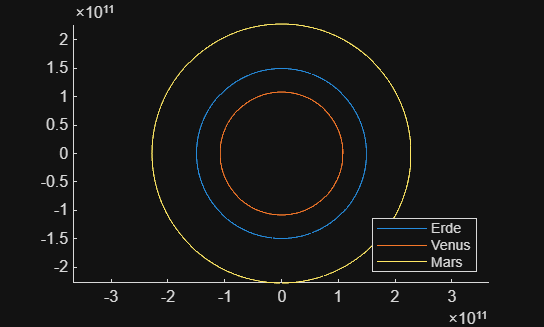

clear all, close all, clc, clf  

tspan = linspace(0,700,100000);
phi0M = -1.71; %Startwinkel für Mars

Earth = posEarth(tspan);
Venus = posVenus(tspan);
Mars = posMars(tspan, phi0M);

figure;
hold on;
plot(Earth(:,1), Earth(:,2));
plot(Venus(:,1), Venus(:,2));
plot(Mars(:,1), Mars(:,2));
axis equal;
legend({"Erde", "Venus", "Mars"}, 'Location', 'southeast')

**2) Gravitationsfeld **

%Startposition der Venus abgreifen
rV = posVenus(0)';
%Von 100km bis 1 Milliarde km 
dmin = 1e5;
dmax = 1e12;

f = @(d) venus_ratio(d,phi0M,rV);
dsolve = fzero(f,[dmin;dmax]); 
fprintf("Abstand zu Venus bei 0.01 der Gravitation = %.f km",dsolve/1000)

Abstand zu Venus bei 0.01 der Gravitation = 1693196 km

**3) Bahnkurve einer Sonde in 1 Jahr (365.25 Tage)**

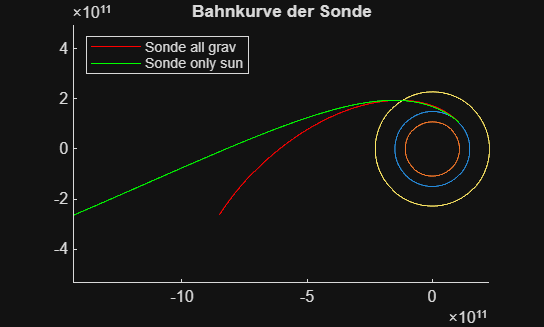

v0 = 15 * 10^3 * 86400; %Startgeschwindigkeit, Meter/Tage
angle = 0; %Startwinkel für einen tangentialen Start zur Erdlaufbahn
options = odeset("AbsTol",1e-8, "RelTol",1e-6, "MaxStep", 0.01);

% Funktion addiert Erdgeschwindigkeit, richtet nach Winkel aus
[pos, v0_vec] = v0_calc(v0, angle);
% Flugbahn der Sonde mit allen Gravitationen
[~, y] = ode113(@(t,y) grav_calc(t,y,phi0M), tspan, [pos'; v0_vec], options);
sonde_all_grav = plot(y(:,1), y(:,2), "r-"); 
hold on;

%Flugbahn der Sonde mit ausschließlich der Sonnengravitation
[t_sun, y_sun] = ode45(@grav_sun, tspan, [pos'; v0_vec], options);
sonde_only_sun = plot(y_sun(:,1), y(:,2),"g-");

legend([sonde_all_grav,sonde_only_sun],{"Sonde all grav","Sonde only sun"}, 'Location','northwest')
title("Bahnkurve der Sonde")

**4) Trajektorie**

v0 = 13.333 * 10^3 * 86400;     %Startgeschwindigkeit, Meter/Tage
target_dist = 12300 * 10^3;     % 20.000 km in Metern

%Eingrenzung der Startwerte
test_angles = linspace(0, -1.8, 36);
test_diffs = zeros(size(test_angles));

for i = 1:length(test_diffs)
    test_diffs(i) = flybyV_dist(test_angles(i), v0, phi0M, target_dist);
end

[mindis, idx] = min(test_diffs);
test_angles(idx);

ans = -1.5943


objective_min = @(a) (flybyV_dist(a, v0, phi0M, target_dist))^2;

start_angle = test_angles(idx); %Startwert
best_angle = fminsearch(objective_min, start_angle);
fprintf('Optimaler Winkel: %.8f rad\n', best_angle);

Optimaler Winkel: -1.61172076 rad


**5) Mars **

objective_min = @(phi) (flybyM_dist(phi, best_angle, v0))^2;
start_phi = -0.5; %Startwert
best_phi = fminsearch(objective_min, start_phi);

[~, min_dist, flyby_t] = flybyM_dist(best_phi, best_angle, v0);

fprintf("Optimaler Startwinkel Mars: %.2f rad", best_phi);

Optimaler Startwinkel Mars: -1.70 rad

fprintf("Minimaler Abstand: %.0f km", min_dist/1000);

Minimaler Abstand: 10000 km

fprintf("Flyby-Zeitpunkt: %.2f Tage", flyby_t);

Flyby-Zeitpunkt: 405.55 Tage

Ergebnisse darstellen

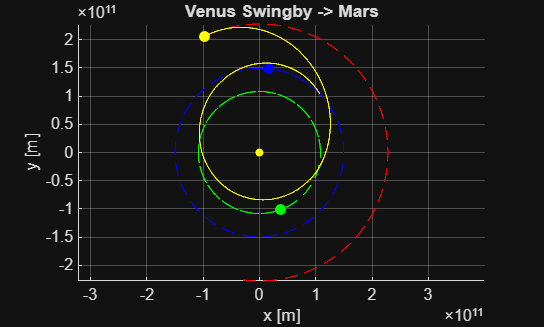

% Simulation bis zum Mars-Treffzeitpunkt
tspan = [0 (flyby_t)];

[pos0, v0_vec] = v0_calc(v0, best_angle);
y0 = [pos0(:); v0_vec(:)];

options = odeset("AbsTol",1e-10,"RelTol",1e-8);

[t, y] = ode113(@(t,y) grav_calc(t,y,best_phi), tspan, y0, options);

ref_plot = 1000;                               %Nummer Zeitschritte der Animation
t_plot = linspace(t(1), t(end), ref_plot);     %Zeit-Vektor für Animation erstellen


rS = y(:,1:2);                              %Position Sonde

%Pos-Daten auf t_plot intepolieren, gleichmäßige Darstellung
%Sonst zu viele Schritte bei steiferen Stellen
rS_plot = interp1(t, rS, t_plot);           
 
%Planeten-Positionen berechnen
rE = posEarth(t_plot);


rV = posVenus(t_plot);
rM = posMars(t_plot, best_phi);

rV_calc = posVenus(t);
%Für Distanzberechnung, ungenau nach Interpolation

%Kreibahnen Planeten
tt = linspace(0, max(t), 500);
bE = posEarth(tt);
bV = posVenus(tt);
bM = posMars(tt, best_phi);

figure
hold on
axis equal
grid on

%Bahnen (gestrichelt)
plot(bE(:,1), bE(:,2), 'b--')
plot(bV(:,1), bV(:,2), 'g--')
plot(bM(:,1), bM(:,2), 'r--')

%Sonne in Mitte einzeichnen, nicht realitätsgetreu skaliert!
Rsun = 7e9;                 
theta = linspace(0,2*pi,50);
fill(Rsun*cos(theta), Rsun*sin(theta), "y", "EdgeColor","none")     %Kreis ausfüllen, kein Rand

% Animierte Objekte (Startwerte)
hE = plot(rE(1,1), rE(1,2), "bo", "MarkerFaceColor","b");
hV = plot(rV(1,1), rV(1,2), "go", "MarkerFaceColor","g");
hM = plot(rM(1,1), rM(1,2), "ro", "MarkerFaceColor","r");
hS = plot(rS(1,1), rS(1,2), "yo", "MarkerFaceColor","y");

% Spur der Sonde
trail = plot(rS(1,1), rS(1,2), "y-");

xlabel('x [m]')
ylabel('y [m]')
title('Venus Swingby -> Mars')

N = length(t_plot);
skip = 1;               %Geschwindigkeit festlegen



for k = 1:skip:N

    set(hE, 'XData', rE(k,1), 'YData', rE(k,2))
    set(hV, 'XData', rV(k,1), 'YData', rV(k,2))
    set(hM, 'XData', rM(k,1), 'YData', rM(k,2))
    set(hS, 'XData', rS_plot(k,1), 'YData', rS_plot(k,2))

    set(trail, 'XData', rS_plot(1:k,1), 'YData', rS_plot(1:k,2))

    drawnow
end

d = vecnorm(rV_calc - rS, 2, 2);  % euklidische Distanz je Zeitpunkt
distMin = min(d);
fprintf("Minimale Distanz zu Venus: %.2f", distMin/1000)

Minimale Distanz zu Venus: 12298.80

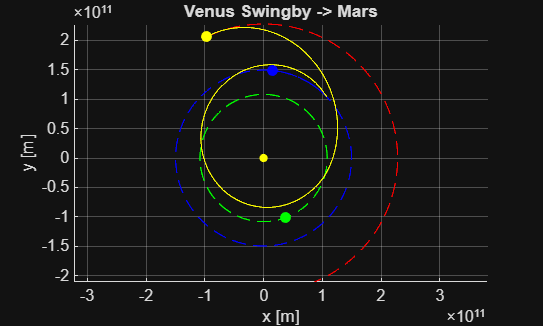



[kin_energy, pot_energy, sum_energy] = energy_calc(y);


hold off;

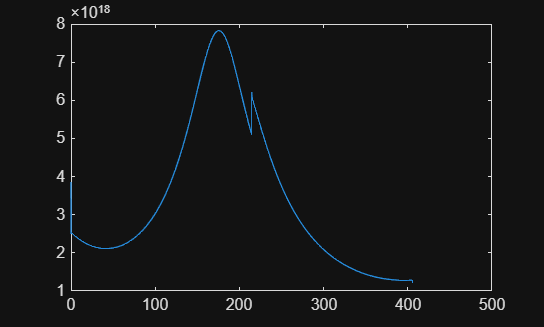

plot(t, kin_energy)

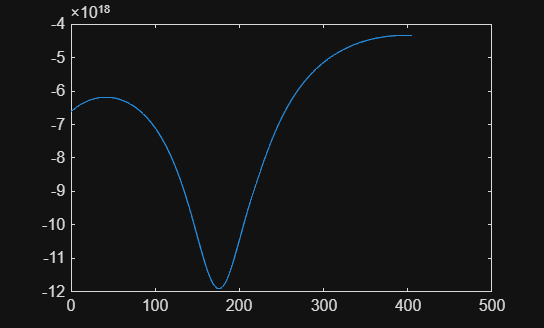

xlabel('Zeit [t]')

figure;
hold off;
plot(t, pot_energy);

hold off;

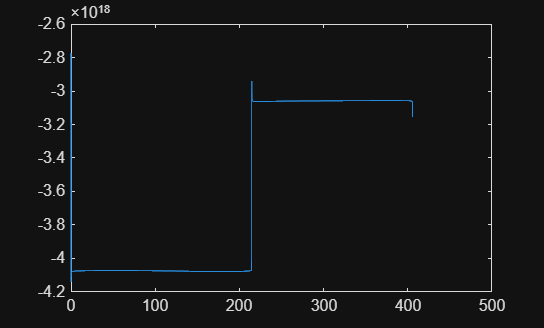

plot(t, sum_energy);

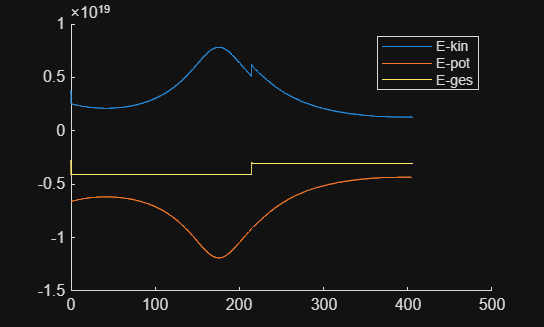


figure;
hold on;
plot(t, kin_energy)
plot(t, pot_energy);
plot(t, sum_energy);
legend("E-kin", "E-pot", "E-ges")